# Problem Set 4

## Problem 1

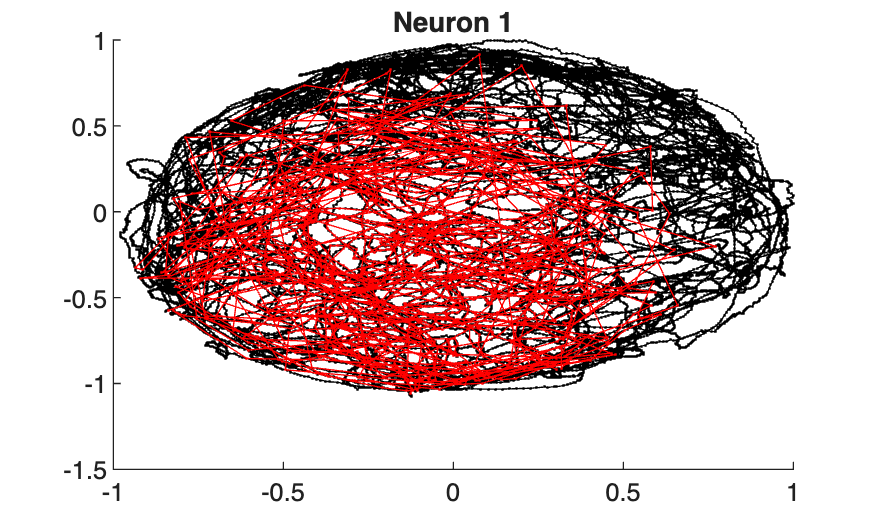

% Part A
figure;
hold on
plot(xN, yN, 'Marker', '.', 'Color', 'k', 'MarkerSize', 1)
spike_idx = find(spikes);
plot(xN(spike_idx), yN(spike_idx), 'Marker', '.', 'Color', 'r', 'MarkerSize', 1);
title('Neuron 1')

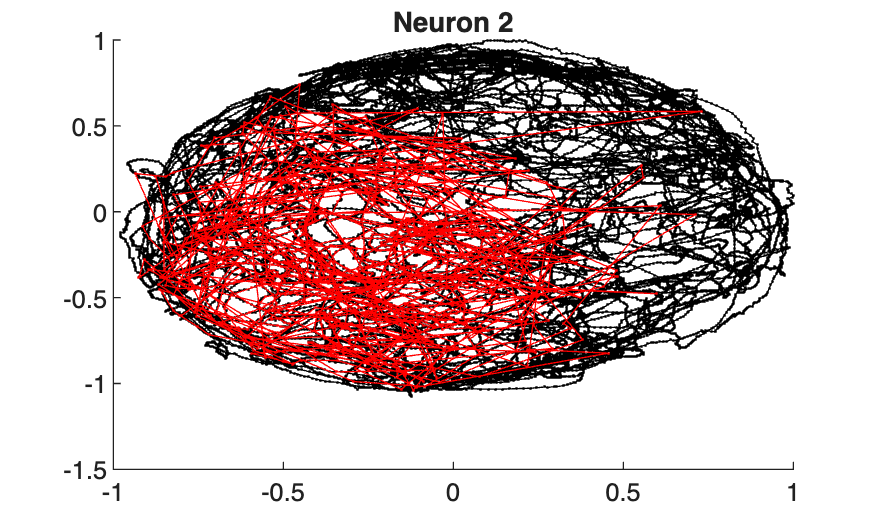


figure;
hold on
plot(xN, yN, 'Marker', '.', 'Color', 'k', 'MarkerSize', 1)
spike2_idx = find(spikes2);
plot(xN(spike2_idx), yN(spike2_idx), 'Marker', '.', 'Color', 'r', 'MarkerSize', 1);
title('Neuron 2')

Neuron 1: This neuron fires when the animal is in the center left location. This suggests that the neuron is preferentially tuned to fire when the animal is in this region. COmpared to Neuron 2, this neuron is less selective and fires at more locations. 

Neuron 2:  This neuron also fires preferentially when the animal is in the leftmost location. The red spikes are highly concentrated in that region. This suggests that the neuron is tuned to a specific spatial location. It fires slightly less broadly than Neuron 1, but both neurons cover similar locations. 

% Part B
[b,dev,stats_line] = glmfit([xN yN],spikes,'poisson');
% b = maximum likelihood estimate [b_0, b_1, b_2]
% dev = model deviance (dev = -2log(theta))
% stats.se = standard error
% stats.p = p-values
disp(stats_line.p)

   1.0e-26 *

         0
    0.8482
    0.0000



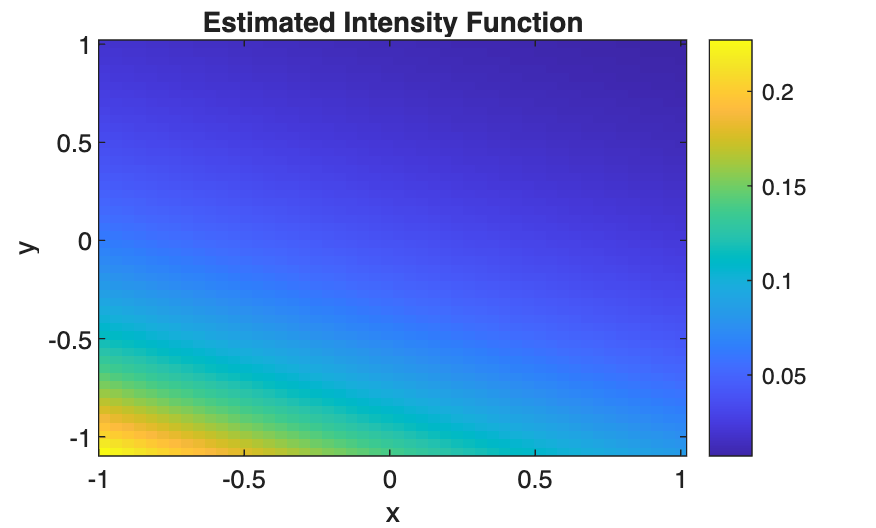

[xgrid, ygrid] = meshgrid(linspace(min(xN), max(xN), 50), ...
                         linspace(min(yN), max(yN), 50));

lambda = exp(b(1) + b(2)*xgrid + b(3)*ygrid);

figure;
imagesc(linspace(min(xN), max(xN), 50), ...
        linspace(min(yN), max(yN), 50), lambda);
axis xy;
colorbar;
title('Estimated Intensity Function');
xlabel('x'); ylabel('y');

The resulting parameters estimates are significant. This does not capture the spatial firing properties of the neuron well. 

% Part C
X = [xN yN xN.^2 yN.^2 xN.*yN];

[b, dev, stats_quad] = glmfit(X, spikes, 'poisson');
disp(stats_quad.p)

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.6196



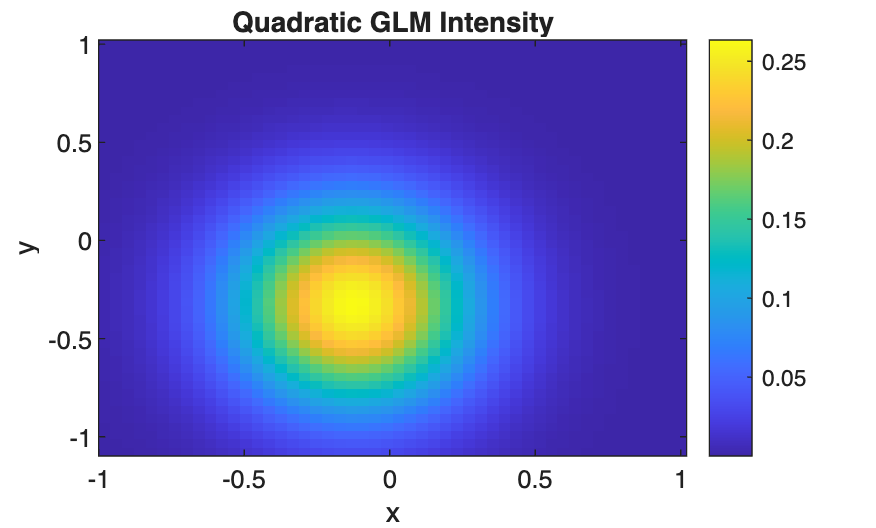

[xgrid, ygrid] = meshgrid(linspace(min(xN), max(xN), 50), ...
                         linspace(min(yN), max(yN), 50));

lambda = exp(b(1) + ...
             b(2)*xgrid + ...
             b(3)*ygrid + ...
             b(4)*xgrid.^2 + ...
             b(5)*ygrid.^2 + ...
             b(6)*xgrid.*ygrid);

figure;
imagesc(linspace(min(xN), max(xN), 50), ...
        linspace(min(yN), max(yN), 50), lambda);
axis xy;
colorbar;
title('Quadratic GLM Intensity');
xlabel('x'); ylabel('y');

The resulting estimates are not all significant. However, the spatial firing properties are much better represented in this plot than compared to the first plot. 

## Problem 2

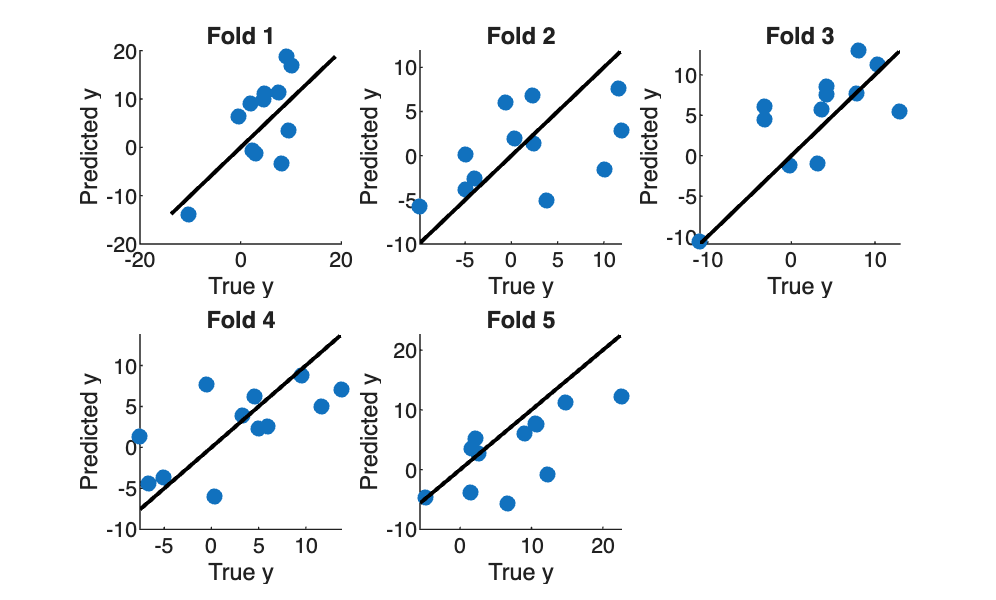

Fold 1: Train VAF = 0.861, Test VAF = 0.075
Fold 2: Train VAF = 0.837, Test VAF = 0.249
Fold 3: Train VAF = 0.824, Test VAF = 0.533
Fold 4: Train VAF = 0.820, Test VAF = 0.522
Fold 5: Train VAF = 0.791, Test VAF = 0.603


% Part A
% predictors X1, outcomes y1

% part i
cv = cvpartition(length(y1), 'KFold', 5);
num_folds = cv.NumTestSets;
error = zeros(num_folds, 1);
VAF_train = zeros(num_folds, 1);
VAF_test  = zeros(num_folds, 1);

figure;
for fold = 1:num_folds
    trainInd = training(cv, fold);
    testInd = test(cv, fold);

    Xtrain = X1(trainInd, :);
    ytrain = y1(trainInd);
    Xtest = X1(testInd, :);
    ytest = y1(testInd);

    Xtrain = [ones(size(Xtrain, 1), 1), Xtrain];
    Xtest = [ones(size(Xtest, 1), 1), Xtest];

    b = Xtrain \ ytrain;
    ypred_test = Xtest * b;
    ypred_train = Xtrain * b;

    % part iii
    VAF_train(fold) = 1 - sum((ytrain - ypred_train).^2) / sum(ytrain.^2);
    VAF_test(fold) = 1 - sum((ytest - ypred_test).^2) / sum(ytest.^2);
    fprintf('Fold %d: Train VAF = %.3f, Test VAF = %.3f\n', ...
            fold, VAF_train(fold), VAF_test(fold));

    % part ii
    subplot(2,3,fold);
    scatter(ytest, ypred_test, 'filled'); hold on;
    minVal = min([ytest; ypred_test]);
    maxVal = max([ytest; ypred_test]);
    plot([minVal maxVal], [minVal maxVal], 'k-', 'LineWidth', 1.5);
    xlabel('True y');
    ylabel('Predicted y');
    title(['Fold ' num2str(fold)]);
    
    error(fold) = mean((ytest - ypred_test).^2);
end


mean_error = mean(error);
disp(mean_error);

   33.9540



mean_train_VAF = mean(VAF_train);
mean_test_VAF  = mean(VAF_test);

fprintf('Average Train VAF = %.3f\n', mean_train_VAF);

Average Train VAF = 0.827


fprintf('Average Test VAF  = %.3f\n', mean_test_VAF);

Average Test VAF  = 0.396


part iv: Because the model is fit on the training data, the train VAF will be higher than the test VAF. The model has not seen the test data and therefore does worse on this data than on the train data, because it does not generalize well. This could be because the model might be overfitting to the training data and cannot generalize to the test data as a result. 

part v: Theoretically, the upper bound for the train VAF and the test VAF is 1.0. This would happen if the model perfectly fit to the training data or test data, respectively. However, this will likely never happen since the model has not seen the test data before, it is unlikely to be able to fit perfectly to it. The train VAF can never be negative. This is because the model does at least as well as predicting the mean which should give train VAF = 0. Since we are trying to minimize the residual sum of the squares with this method, we can never do worse than the mean which is 0. The test VAF can be negative because the model was never fit to the test data. It is possible for the test VAF to do worse than the train VAF as a result. If the residual variance on the test set exceeds the total variance, the VAF can be negative. 

## Part B

cv = cvpartition(length(y1), 'KFold', 5);
num_folds = cv.NumTestSets;

error = zeros(num_folds, 1);
VAF_train = zeros(num_folds, 1);
VAF_test  = zeros(num_folds, 1);

for fold = 1:num_folds
    trainInd = training(cv, fold);
    testInd  = test(cv, fold);

    Xtrain = X1(trainInd, :);
    ytrain = y1(trainInd);
    Xtest  = X1(testInd, :);
    ytest  = y1(testInd);

    Xtrain = [Xtrain, Xtrain.^2];
    Xtest  = [Xtest,  Xtest.^2];

    Xtrain = [ones(size(Xtrain, 1), 1), Xtrain];
    Xtest  = [ones(size(Xtest, 1), 1), Xtest];

    b = Xtrain \ ytrain;

    ypred_train = Xtrain * b;
    ypred_test  = Xtest * b;

    VAF_train(fold) = 1 - sum((ytrain - ypred_train).^2) / sum(ytrain.^2);
    VAF_test(fold)  = 1 - sum((ytest - ypred_test).^2) / sum(ytest.^2);

    fprintf('Fold %d: Train VAF = %.3f, Test VAF = %.3f\n', ...
            fold, VAF_train(fold), VAF_test(fold));

    error(fold) = mean((ytest - ypred_test).^2);
end

Fold 1: Train VAF = 0.921, Test VAF = -6.257
Fold 2: Train VAF = 0.931, Test VAF = -13.080
Fold 3: Train VAF = 0.950, Test VAF = -4.891
Fold 4: Train VAF = 0.956, Test VAF = -0.860
Fold 5: Train VAF = 0.972, Test VAF = -0.824



mean_error = mean(error);
mean_train_VAF = mean(VAF_train);
mean_test_VAF  = mean(VAF_test);

fprintf('\nAverage MSE = %.3f\n', mean_error);


Average MSE = 313.100


fprintf('Average Train VAF = %.3f\n', mean_train_VAF);

Average Train VAF = 0.946


fprintf('Average Test VAF  = %.3f\n', mean_test_VAF);

Average Test VAF  = -5.182


The train VAF increased from part A, but the test VAF decreased significantly from part A. This is likely because the model started to overfit to the train data. This made it so that the model performed better on the train data, but could not generalize to the test data. The extra parameters might have made it so that the data fit to the noise in the train set, which made the predictions in the test set much worse. 

## Part C

% predictors X2, outcomes y2
% part i
cv = cvpartition(length(y1), 'KFold', 5);
num_folds = cv.NumTestSets;
error = zeros(num_folds, 1);
VAF_train = zeros(num_folds, 1);
VAF_test  = zeros(num_folds, 1);

for fold = 1:num_folds
    trainInd = training(cv, fold);
    testInd = test(cv, fold);

    Xtrain = X2(trainInd, :);
    ytrain = y2(trainInd);
    Xtest = X2(testInd, :);
    ytest = y2(testInd);

    Xtrain = [ones(size(Xtrain, 1), 1), Xtrain];
    Xtest = [ones(size(Xtest, 1), 1), Xtest];

    b = Xtrain \ ytrain;
    ypred_test = Xtest * b;
    ypred_train = Xtrain * b;

    % part iii
    VAF_train(fold) = 1 - sum((ytrain - ypred_train).^2) / sum(ytrain.^2);
    VAF_test(fold) = 1 - sum((ytest - ypred_test).^2) / sum(ytest.^2);
    fprintf('Fold %d: Train VAF = %.3f, Test VAF = %.3f\n', ...
            fold, VAF_train(fold), VAF_test(fold));

    error(fold) = mean((ytest - ypred_test).^2);
end

Fold 1: Train VAF = 0.536, Test VAF = 0.308
Fold 2: Train VAF = 0.763, Test VAF = -2.173
Fold 3: Train VAF = 0.624, Test VAF = -0.798
Fold 4: Train VAF = 0.608, Test VAF = 0.125
Fold 5: Train VAF = 0.591, Test VAF = 0.067



mean_error = mean(error);
disp(mean_error);

   56.0591



mean_train_VAF = mean(VAF_train);
mean_test_VAF  = mean(VAF_test);

fprintf('\nAverage Train VAF = %.3f\n', mean_train_VAF);


Average Train VAF = 0.624


fprintf('Average Test VAF  = %.3f\n', mean_test_VAF);

Average Test VAF  = -0.494


Compared to part A, the test VAF and the train VAF dropped. This change is not for the same reason as in part B. In part C, the model is not fitting to the training data well, unlike in part B. This suggests that the model is underfitting instead of overfitting. I would think the linear model does not perform well because the predictors of X2 are correlated. If the predictors are correlated, the least squares solution cannot find coefficients that fit the data well because the columns will be very similar to each other. Different training folds will then produce very different values of coefficients. 

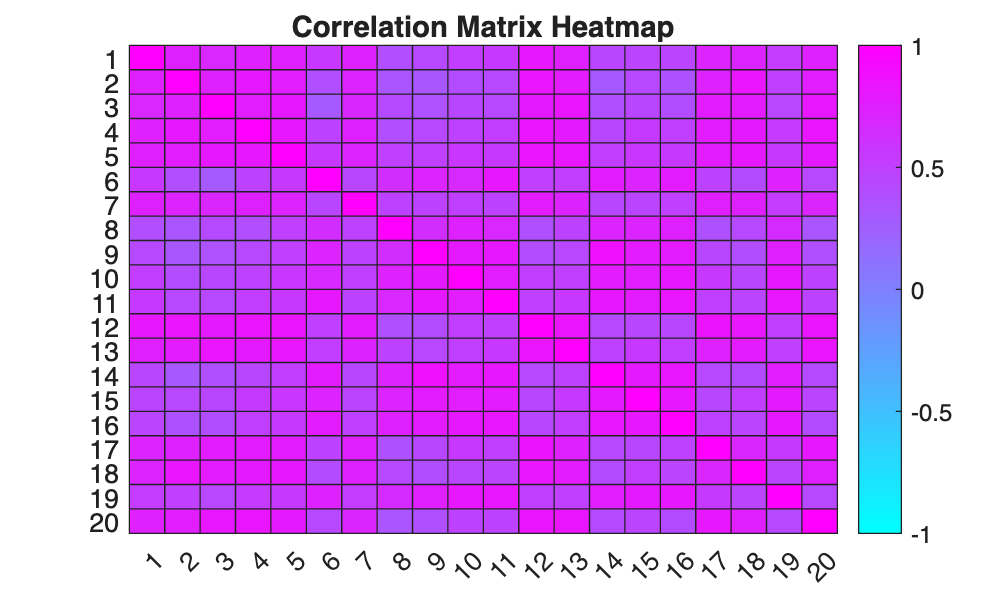

corr_matrix = corr(X2);

figure;
heatmap(corr_matrix, ...
    'Colormap', cool, ...
    'ColorLimits', [-1 1], ...
    'ColorbarVisible', 'on');

title('Correlation Matrix Heatmap');

To test the hypothesis, I made a correlation matrix heatmap. This shows that almost all correlations are close to 1, meaning that all of the predictors are highly correlated to one another. 